# Stability

We can imagine transfer functions with zeros and poles just about anywhere.  

- For a *proper* transfer function the number of zeros equals the number of poles

- For a *strictly proper* transfer function the number of zeros is less than the number of poles.

- When there are more zeros than poles the transfer function is *improper*.

Here are some arbitrary locations.

zeros = [ -1 , -3, -5,...
    -5+10*1i, -5-10*1i,...
    +1, + 2, -15 ]

zeros =   -1.0000 + 0.0000i  -3.0000 + 0.0000i  -5.0000 + 0.0000i  -5.0000 +10.0000i  -5.0000 -10.0000i   1.0000 + 0.0000i   2.0000 + 0.0000i -15.0000 + 0.0000i


poles = [ -2.5, -4, -6, -8, ...
    -1+5*1i, -1-5*1i, ...
    -10, -20 ]

poles =   -2.5000 + 0.0000i  -4.0000 + 0.0000i  -6.0000 + 0.0000i  -8.0000 + 0.0000i  -1.0000 + 5.0000i  -1.0000 - 5.0000i -10.0000 + 0.0000i -20.0000 + 0.0000i


**Remember that complex zeros and poles must come in complex conjugate pairs.**

In MATLAB you can make a transfer function from the poles and directly.

G = zpk(zeros,poles,1)

G =
 
                                       
  (s+1) (s+3) (s+5) (s+15)             
                                       
          (s-1) (s-2) (s^2 + 10s + 125)
                                       
                                       
  -------------------------------------
                                       
  (s+2.5) (s+4) (s+6) (s+8)            
                                       
          (s+10) (s+20) (s^2 + 2s + 26)
                                       
                                       
 
Continuous-time zero/pole/gain model.



Here we made the gain in zpk equal to one. It doesn't matter for now.

Here is a pole-zero map for the system $G$.

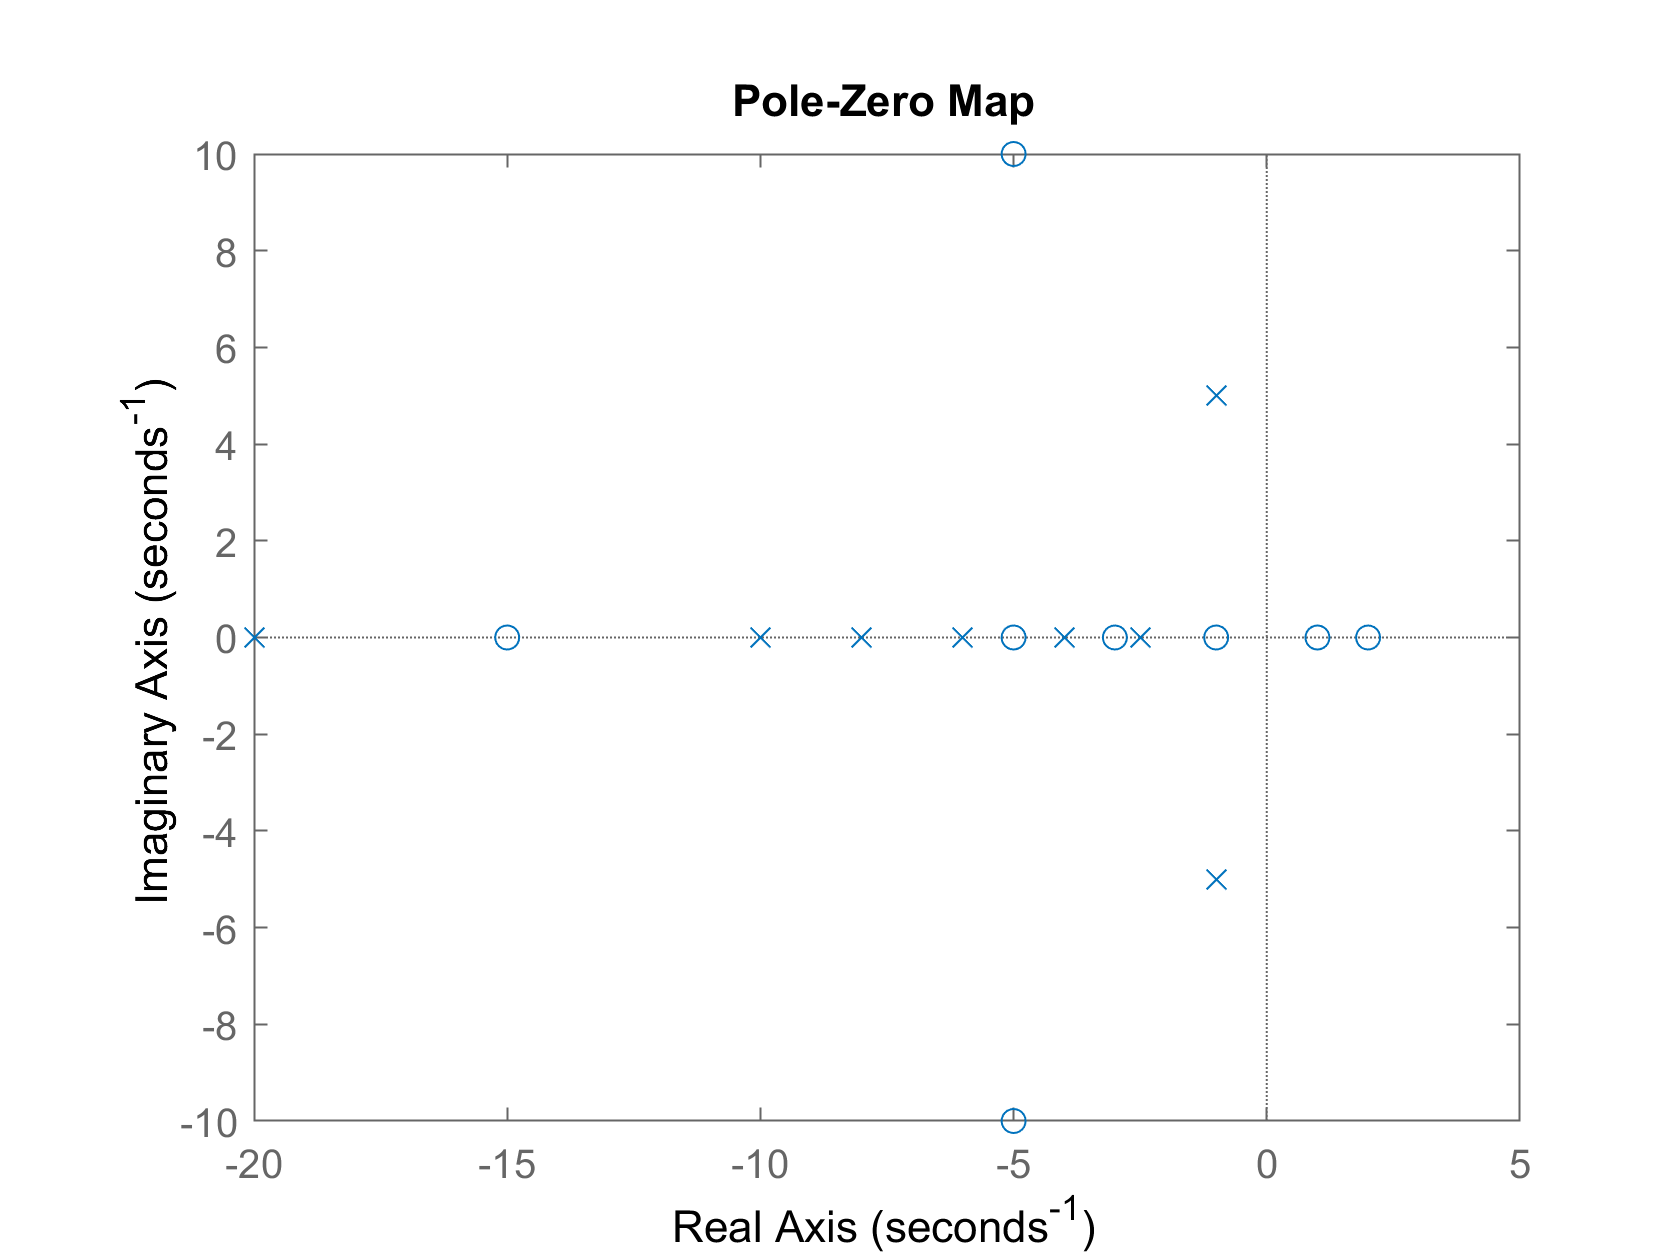

pzmap(G)

Let's look at the impulse and step responses.

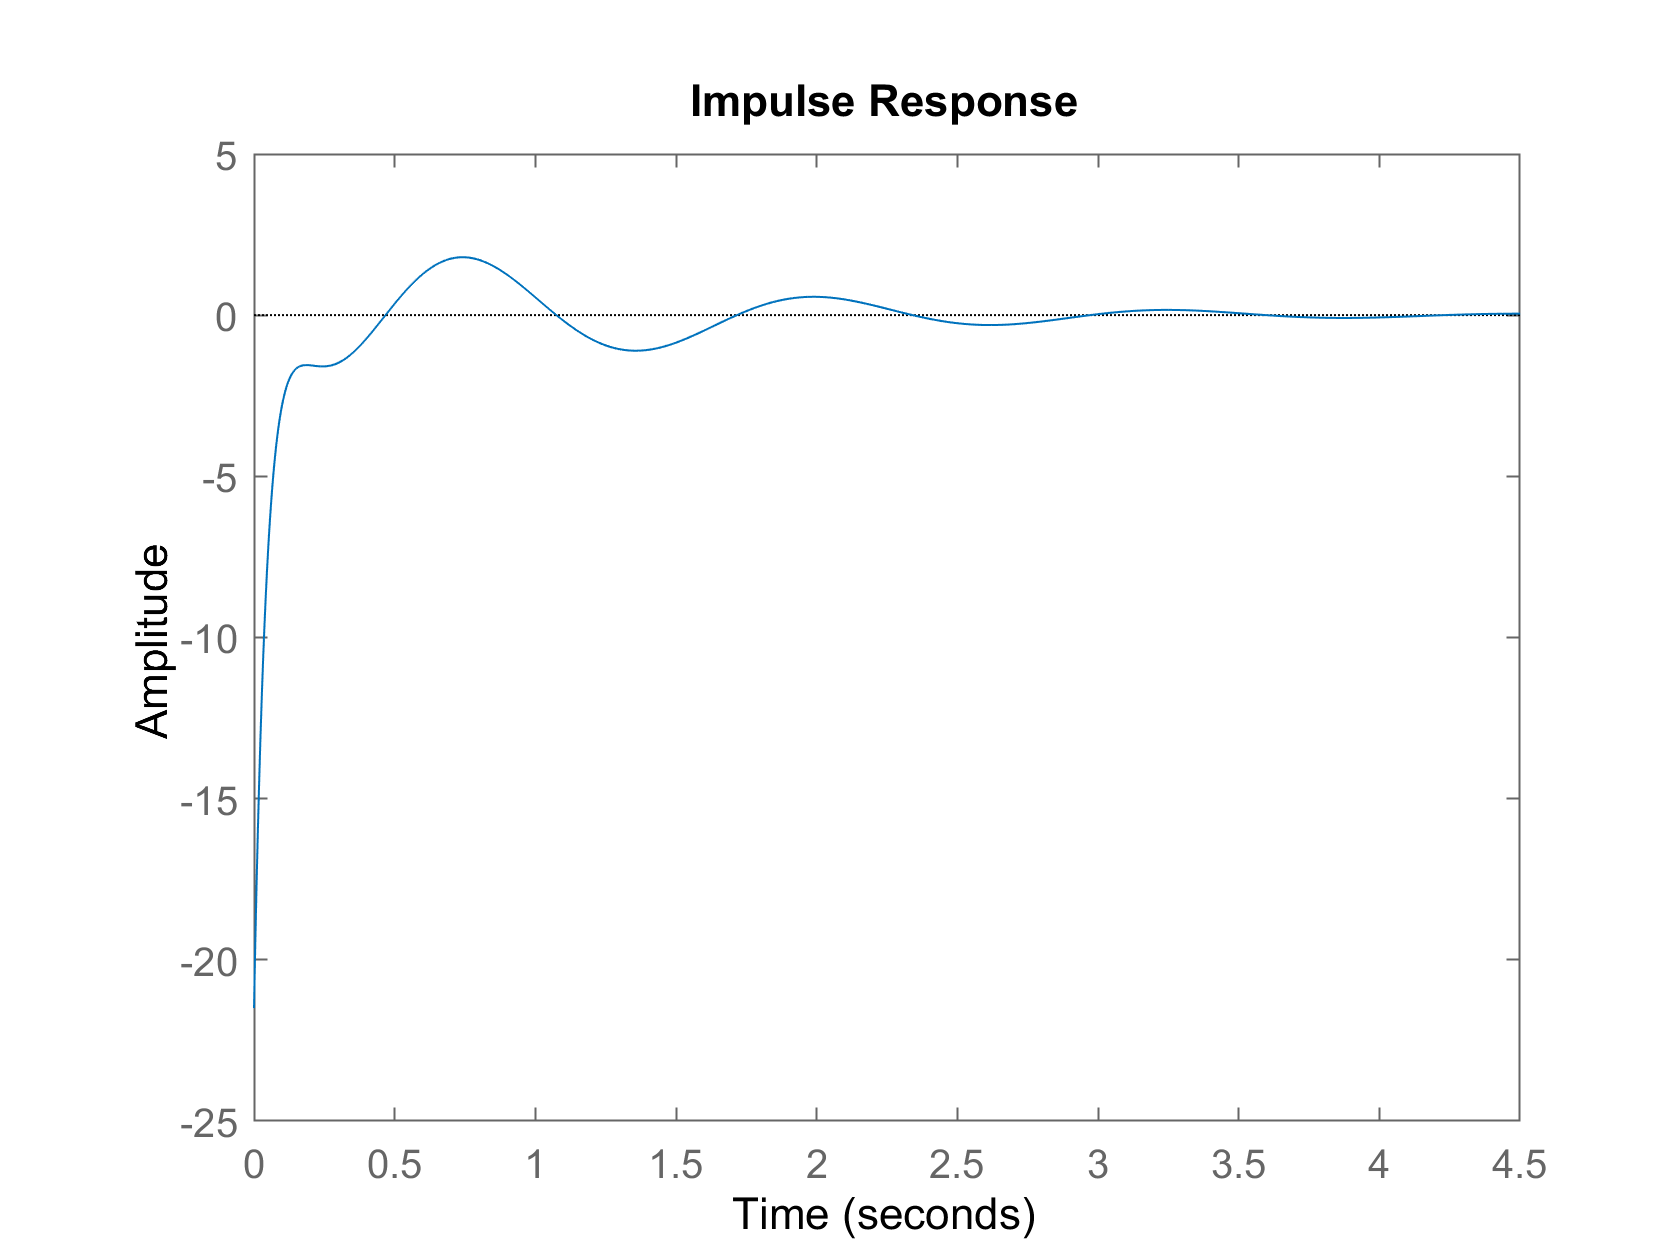

impulse(G)

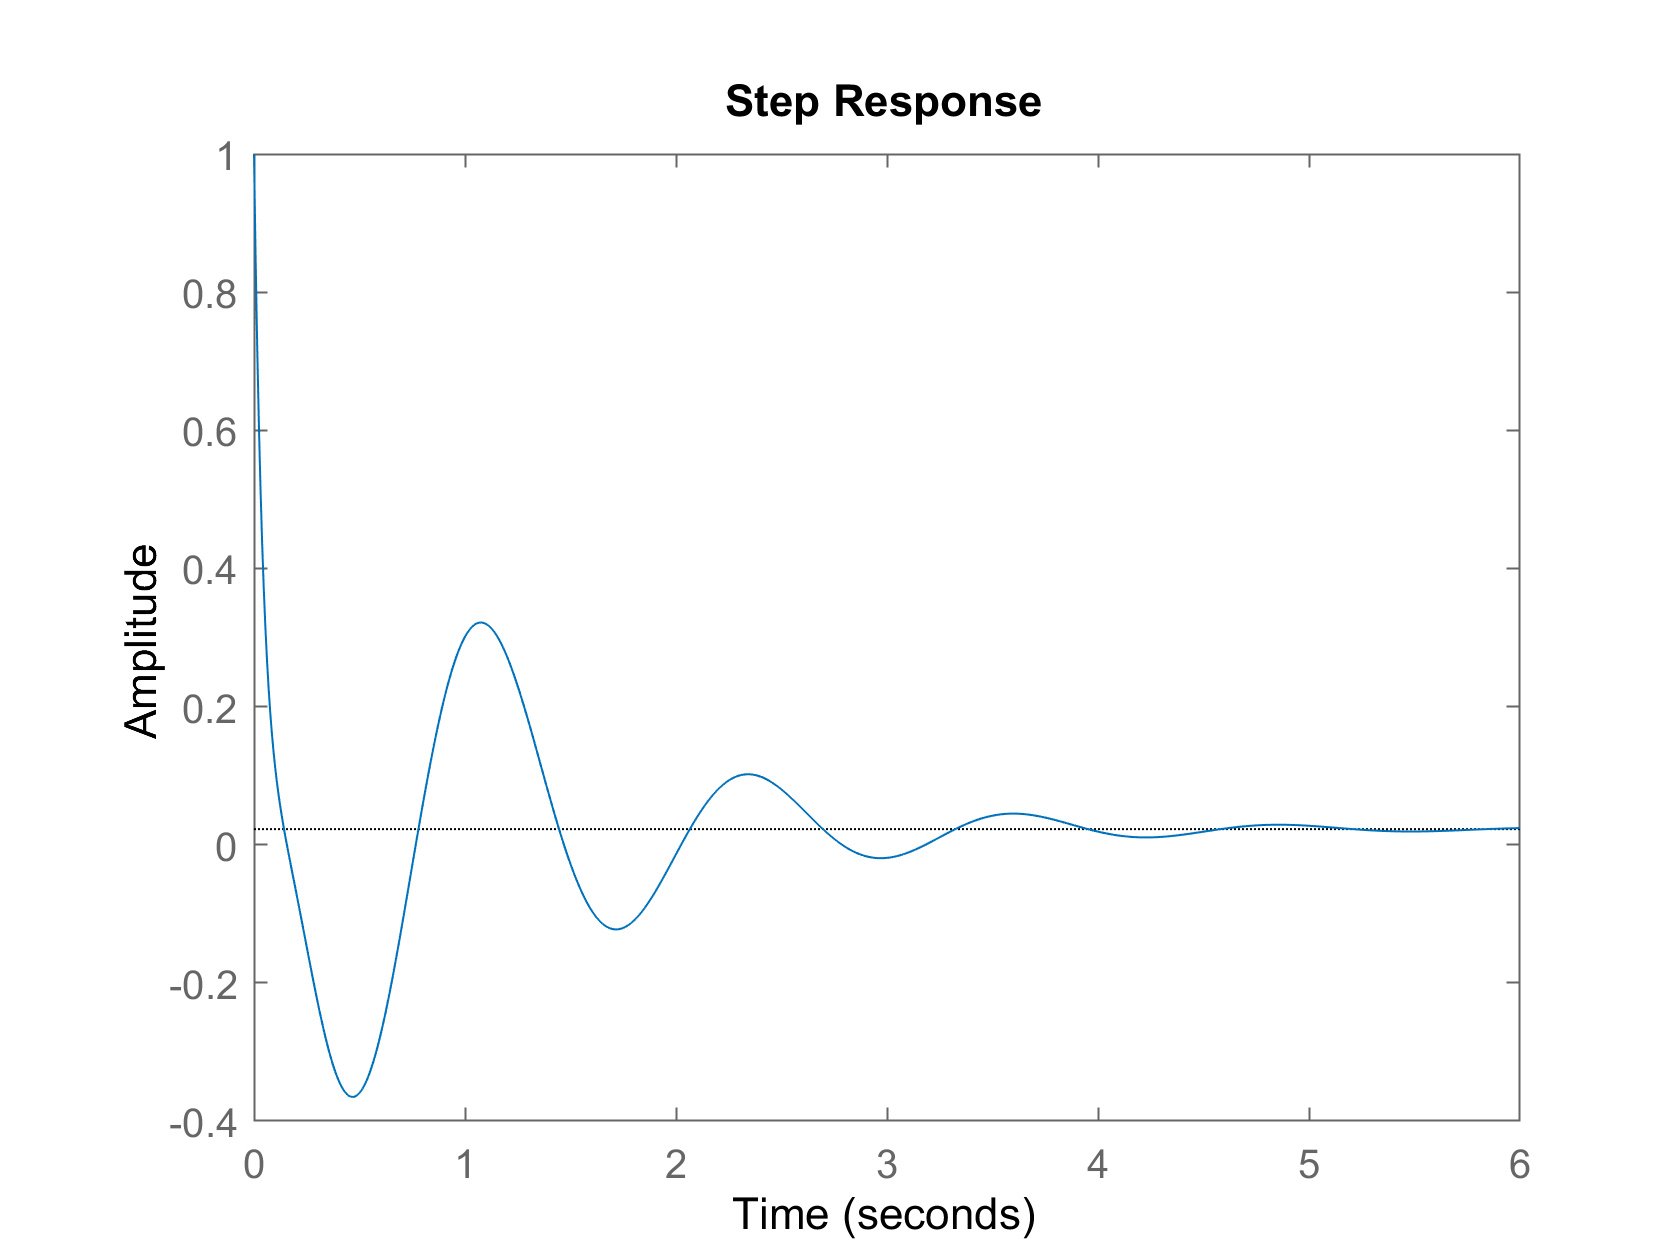

step(G)

## Stability

Remember the stability criterion.

*For a system to be stable all of its poles must be in the LHP*

Try changing the poles and zeros and see the affect on stability.  You should note that zeros in the RHP (right-half plane) do not affect stability, but if *any* pole is in the RHP the system response grows without bound.